# Behavioural analysis

data_struct = loadData();
subjects = data_struct.keys

subjects = 1×15 cell array
    {'601PaTu'}    {'602SuYe'}    {'905DiSt'}    {'906ElFl'}    {'906IsAg'}    {'907AlOt'}    {'908LeEm'}    {'909CaNa'}    {'910EmCo'}    {'911RiBa'}    {'912SuYe'}    {'915AdEl'}    {'918ShTe'}    {'998ChGo'}    {'999MaMa'}


%add nice things to path
addpath('C:\Users\mmazor\Documents\software\cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');

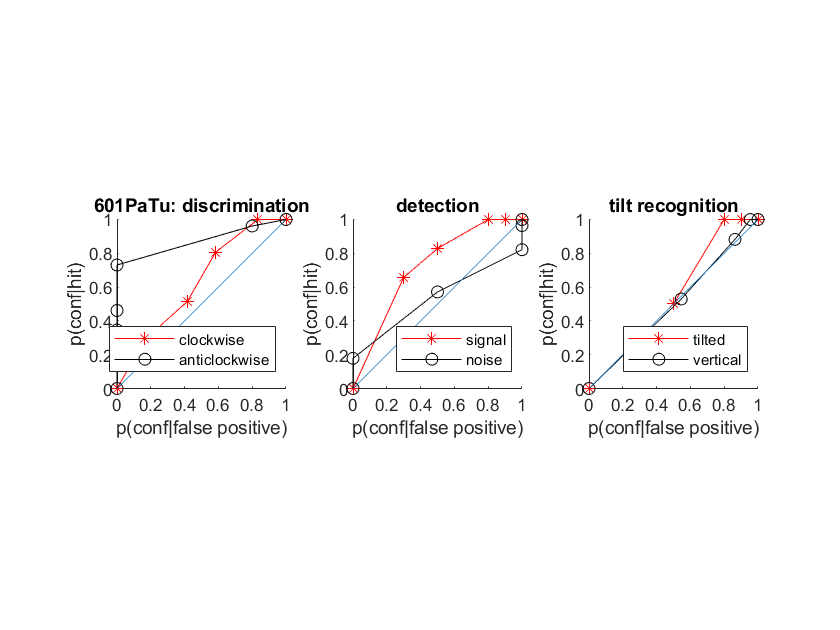

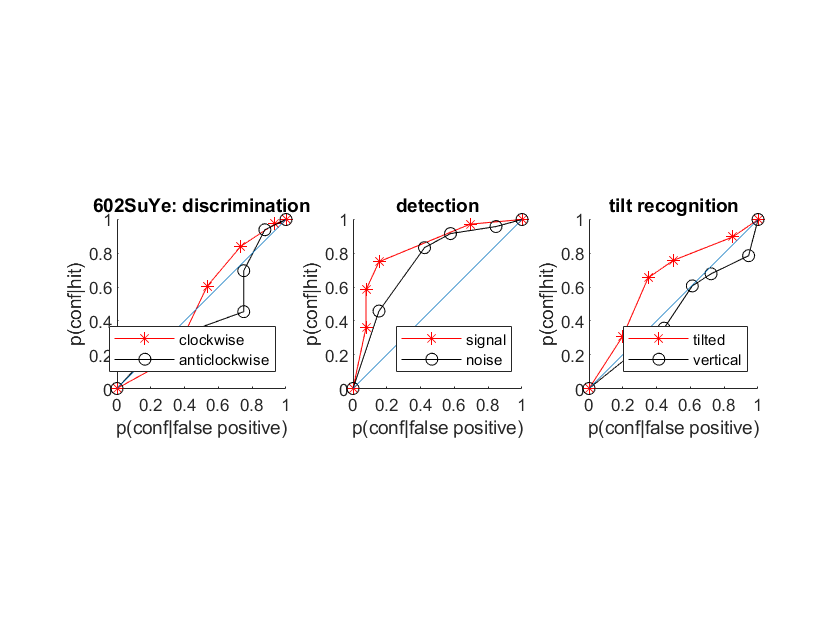

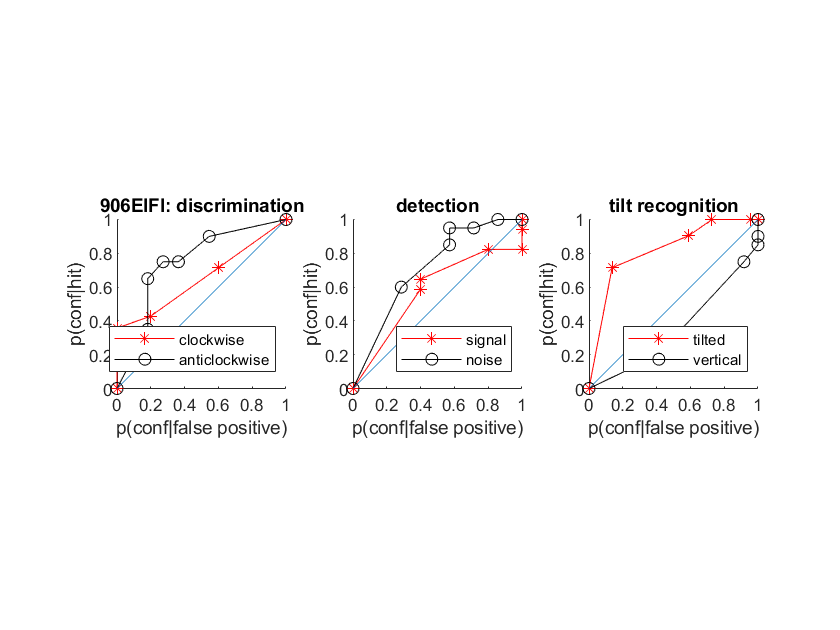

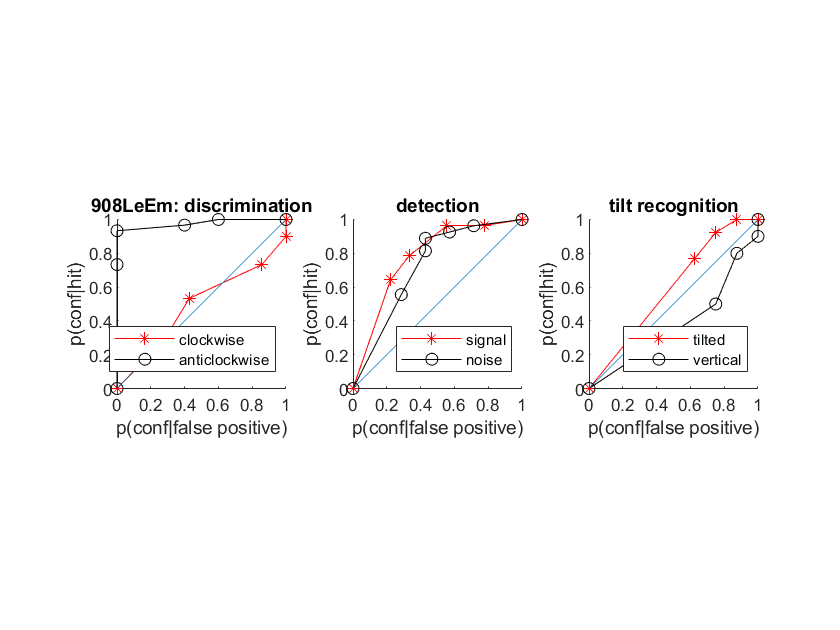

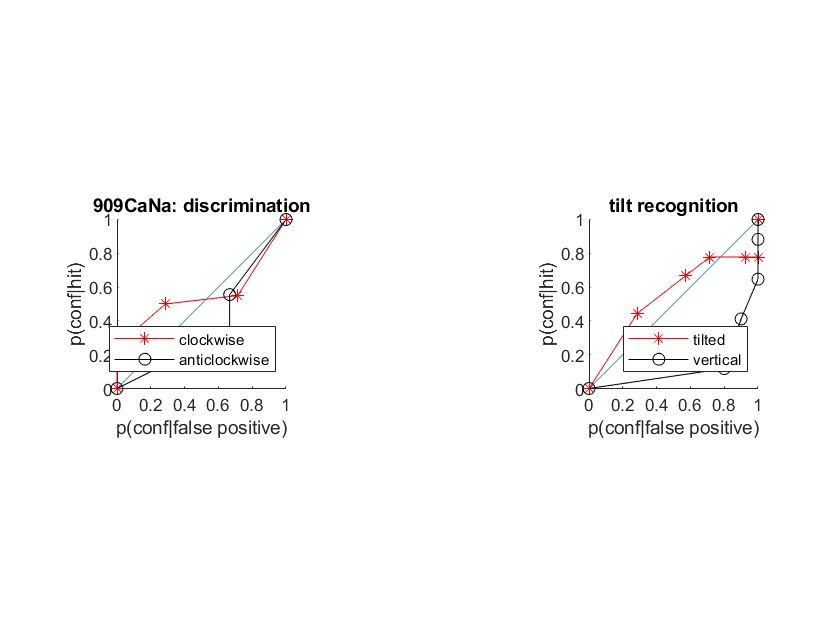

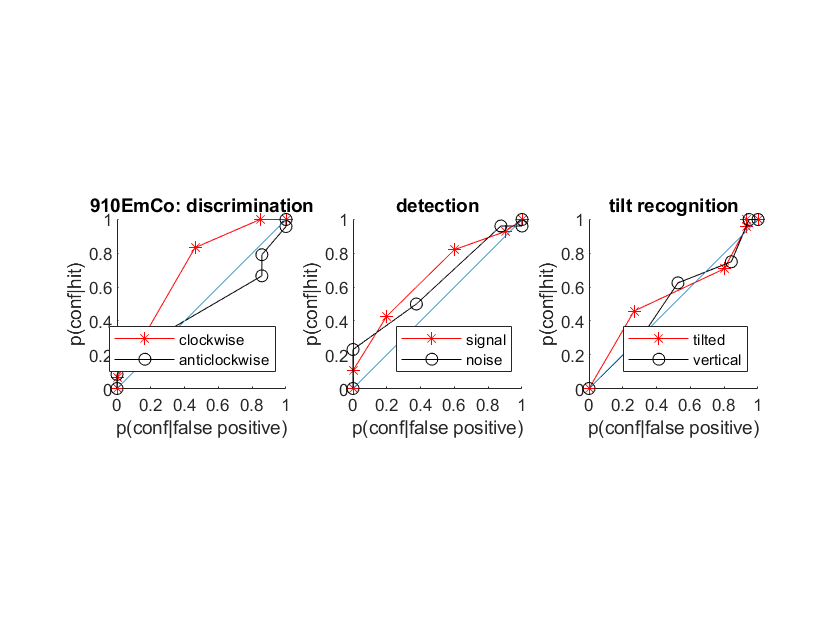

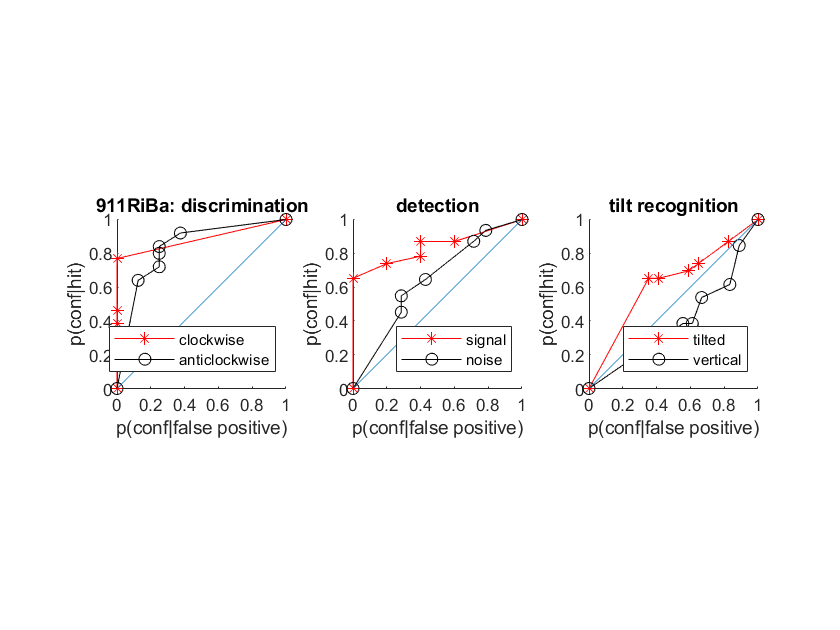

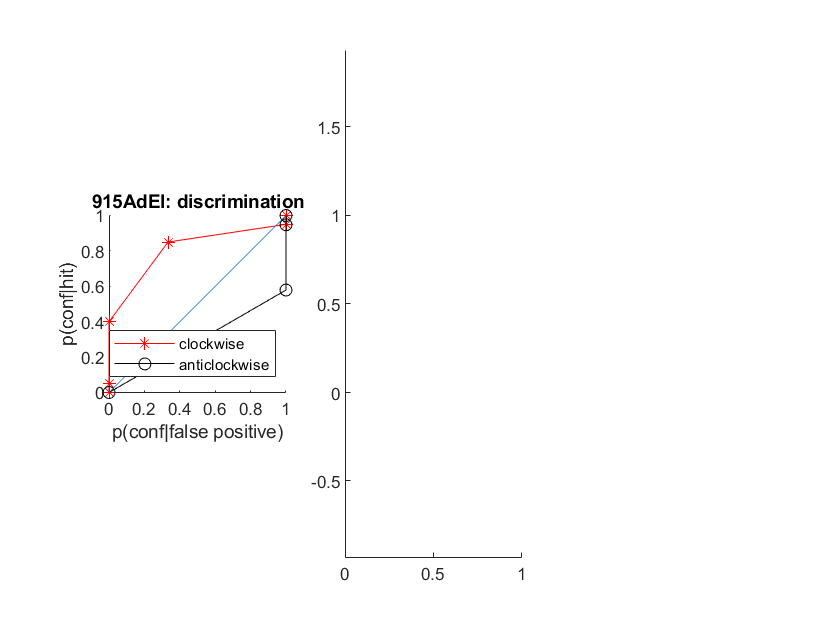

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);
[TTGroup, TVGroup, VTGroup, VVGroup] = deal([]);
[nR_S1,nR_S2,nR_signal_nR_noise, nR_tilted, nR_vertical] = deal([]);


for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);

    if sum(subject.DisInclude)>25 && sum(subject.DetInclude)>25 && sum(subject.TiltInclude)>25
    
        %break into taskXresponseXsignal
        DisCC = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1 & subject.DisInclude),1:6);
        DisCA = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0 & subject.DisInclude),1:6);
        DisAC = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1 & subject.DisInclude),1:6);
        DisAA = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0 & subject.DisInclude),1:6);
        
        DetSignalYes = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1 & subject.DetInclude),1:6);
        DetSignalNo = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0 & subject.DetInclude),1:6);
        DetNoiseYes = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1 & subject.DetInclude),1:6);
        DetNoiseNo = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0 & subject.DetInclude),1:6);
        
        TiltTT = histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==1 & subject.TiltInclude),1:6);
        TiltTV = histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==0 & subject.TiltInclude),1:6);
        TiltVT = histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==1 & subject.TiltInclude),1:6);
        TiltVV = histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==0 & subject.TiltInclude),1:6);
        
        nR_S1(s,:) = [reshape(DisAA(end:-1:1),1,[]) reshape(DisAC,1,[])];
        nR_S2(s,:) = [reshape(DisCA(end:-1:1),1,[]) reshape(DisCC,1,[])];
        nR_signal(s,:) = [reshape(DetSignalNo(end:-1:1),1,[]) reshape(DetSignalYes,1,[])];
        nR_noise(s,:) = [reshape(DetNoiseNo(end:-1:1),1,[]) reshape(DetNoiseYes,1,[])];
        nR_tilted(s,:) = [reshape(TiltTV(end:-1:1),1,[]) reshape(TiltTT,1,[])];
        nR_vertical(s,:) = [reshape(TiltVV(end:-1:1),1,[]) reshape(TiltVT,1,[])];
        
        %% plot discrimination
        figure;
        subplot(1,3,1);
        hold on;
        axis equal
        
        %up responses
        plot([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
            [0; cumsum(DisCC(end:-1:1))/sum(DisCC)], '-*r');
        upAUC(s) = trapz([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
            [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]);
        
        ACGroup = [ACGroup [0; cumsum(DisAC(end:-1:1))/sum(DisAC)]];
        CCGroup = [CCGroup [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]];
    
        %down responses
        plot([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
            [0; cumsum(DisAA(end:-1:1))/sum(DisAA)], '-ok');
        downAUC(s) = trapz([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
            [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]);
        
        AAGroup = [AAGroup [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]];
        CAGroup = [CAGroup [0; cumsum(DisCA(end:-1:1))/sum(DisCA)]];
        
        xlabel('p(conf|false positive)');
        ylabel('p(conf|hit)');
        title([subjects{s}, ': discrimination']);
        set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
        set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
        refline(1,0);
        legend('clockwise', 'anticlockwise', 'Location', 'southeast')
        
        %% plot detection
        if sum(subject.DetSignal==0 & subject.DetResp==1)>1
            subplot(1,3,2);
            hold on;
            axis equal
            
            %yes responses
            plot([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
                [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)], '-*r');
            
            yesAUC(s) = trapz([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
                [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]);
            
            NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
            SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
            
            %no responses
            plot([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
                [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)],'-ok');
           noAUC(s) = trapz([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
                [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]);
        
            NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
            SignalNoGroup = [SignalNoGroup [0;
                cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
            
            xlabel('p(conf|false positive)');
            ylabel('p(conf|hit)');
            title('detection');
            set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
            set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
            refline(1,0);
            legend('signal', 'noise', 'Location', 'southeast')
        end
        
        %% plot tilt
        if sum(subject.TiltSignal==0 & subject.TiltResp==1)>1
            subplot(1,3,3);
            hold on;
            axis equal
            
            %tilt responses
            plot([0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)],...
                [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)], '-*r');
            
            tiltAUC(s) = trapz([0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)],...
                [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)]);
            
            VTGroup = [VTGroup [0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)]];
            TTGRoup = [TTGroup [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)]];
            
            %vertical responses
            plot([0; cumsum(TiltTV(end:-1:1))/sum(TiltTV)],...
                [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)],'-ok');
           verticalAUC(s) = trapz([0; cumsum(TiltTV(end:-1:1))/sum(TiltTV)],...
                [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)]);
        
            VVGroup = [VVGroup [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)]];
            TVGroup = [TVGroup [0;
                cumsum(TiltTV(end:-1:1))/sum(TiltTV)]];
            
            xlabel('p(conf|false positive)');
            ylabel('p(conf|hit)');
            title('tilt recognition');
            set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
            set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
            refline(1,0);
            legend('tilted', 'vertical', 'Location', 'southeast')
        end
    end
end